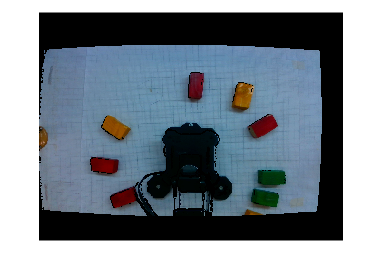

% Starting from default position
sethome(arb);
pause(2);

% Initializing Masks 
[depth_img, imgRGB] = enable_vision();

Transformation Matrix (Camera → Block):
    0.9895   -0.1444         0  -14.6749
    0.1444    0.9895         0    7.0400
         0         0    1.0000   45.9076
         0         0         0    1.0000

Block position: x=14.67 cm, y=7.04 cm, z=45.91 cm
Block orientation: -8.3 deg


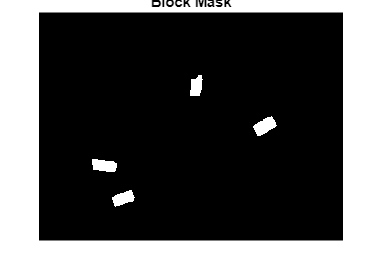

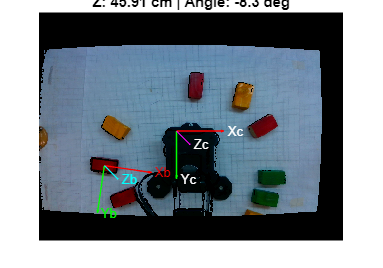

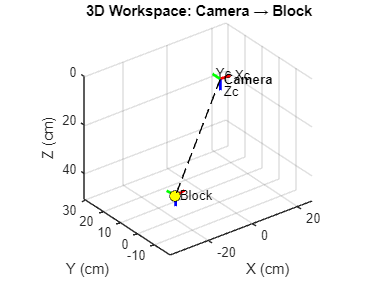

Block is NOT radially aligned (72.7 deg off radial).


[redMask, blueMask, greenMask, yellowMask] = createMasks(imgRGB);

%place location
place_x = 19.5;
place_y = 0;
    
% Getting the coordinates of the block with the selected color
[pick_x, pick_y, pick_z, aligned, shape] = get_position(redMask, imgRGB, depth_img);

% pick_x = pick_x - 2;
if (abs(pick_x) > 22 || abs(pick_y) > 22)
    fprintf("Block out of reach\n");
end

% checking orientation of the block
if (~aligned) 
    fprintf("Block not aligned\n");
end

Block not aligned



if (pick_z > 44)
    pre_z = 8;
    z = 4;
else 
    pre_z = 10.5;
    z = 6.5;
end

%finding IK solutions for pick location

%pre-grasp pose
fprintf("Pre Grasp Pose\n");

Pre Grasp Pose


errorCode = set_optimal(arb, pick_x, pick_y, pre_z);

checksum fail: is 0, should be 193


Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in Arbotix/getpos (line 314)
                        p(j) = Arbotix.e2a( retval.params*[1; 256] );

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('set_optimal', 'C:\Users\itadmin\Desktop\milestone3\Robotics\perceptionPickAndPlace\Yusra_vision\set_optimal.m', 3)" style="font-weight:

if (errorCode ~= 0)
    fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
    sethome(arb);
    return;
end
pause(4);
positionJaw(arb, 0); %end-effector completely open
pause(2);

%grasp pose
fprintf("Grasp Pose\n");
set_optimal(arb,pick_x, pick_y, z);
if (errorCode ~= 0)
    fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
    sethome(arb);
    return;
end
pause(4);
positionJaw(arb, 1.15); %end-effector grasping block
pause(4)
arb.setpos(2, 0, 50);
pause(4);

% %pre-grasp pose
% fprintf("Pre Grasp Pose: Block Picked\n");
% set_optimal(arb, pick_x, pick_y, pre_z);
% pause(5);

% pre-place pose
fprintf("Pre Place Pose\n");
set_optimal(arb, place_x, place_y, pre_z+4);
if (errorCode ~= 0)
    fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
    sethome(arb);
    return;
end
pause(3);

% place pose
fprintf("Place Pose\n");
set_optimal(arb, place_x, place_y, z);
if (errorCode ~= 0)
    fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
    sethome(arb);
    return;
end
pause(3)
positionJaw(arb, 0); %end-effector open enough to release the block
pause(2);

% pre-place pose
fprintf("Pre Place Pose: Block Placed\n");
set_optimal(arb, place_x, place_y, pre_z);
if (errorCode ~= 0)
    fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
    sethome(arb);
    return;
end
pause(3)

%verifying accuracy of placement
[x,y,z,~,~] = pincherFK(arb.getpos());
pos_error = sqrt((x - place_x)^2 + (y - place_y)^2);

if pos_error < 0.5
    fprintf('Placement verified. XY error: %.4f cm\n', pos_error);
    success = true;
else
    fprintf('WARNING: Placement error %.4f cm exceeds tolerance %.4f cm\n', ...
        pos_error, 0.5);
    success = false;
end


%going back to home position
sethome(arb);
pause(5);

fprintf("All cubes placed\n")
sethome(arb);
